# Laboratorium 10

Karolina Piotrowska

## Wstęp

####     Na czym polega proces filtracji?

    Filtracja jest to proces przetwarzania dokonywany na sygnale w dziedzinie czasu. Proces ten powoduje zmiany w widmie sygnału oryginalnego. Zmiana polega na odfiltrowaniu pewnych niepożądanych składowych sygnału wejściowego.

####     Filtry o skończonej odpowiedzi impulsowej (FIR)

    Zasadniczą cechą charakteryzującą ten rodzaj filtrów jest to, że do uzyskania bieżącej próbki sygnału na wyjściu filtru wykorzystują one próbkę bieżącą i próbki przeszłe sygnału wejściowego, nie korzystając z żadnych przeszłych próbek sygnału wyjściowego. Z tego powodu nazywa się je czasem filtrami nierekursywnymi. Nazwa ich wzięła się stąd, że filtry te, dysponując skończoną liczbą różnych od zera próbek sygnału wejściowego, na wyjściu zawsze mają skończoną liczbę próbek sygnału wyjściowego.

####     Okna

    Stosując okna zmniejszamy zafalowania charakterystyki kosztem rozdzielczości

####     Faza filtrów FIR

    Faza filtrów FIR jest liniowa, przez co opóźnienie grupowe jest stałe. Oznacza to, że wszystkie składowe częstotliwościowe sygnału wejściowego są jednakowo opóźniane, a to z kolei oznacza, że nie ma żadnych zniekształceń fazowych w sygnale wyjściowym.

## Rozwiązanie zadań

### Zadanie 1

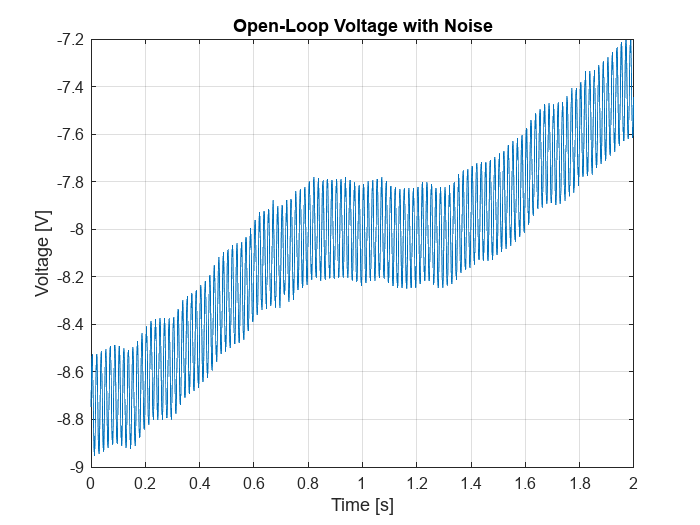

figure
dolne = 50;
gorne = 70;
load openloop60hertz, openLoop=openLoopVoltage;
Fs=1000;
t=(0:length(openLoop)-1)/Fs;
plot(t, openLoop); box on; grid on;
ylabel 'Voltage [V]', xlabel 'Time [s]'
title 'Open-Loop Voltage with Noise'

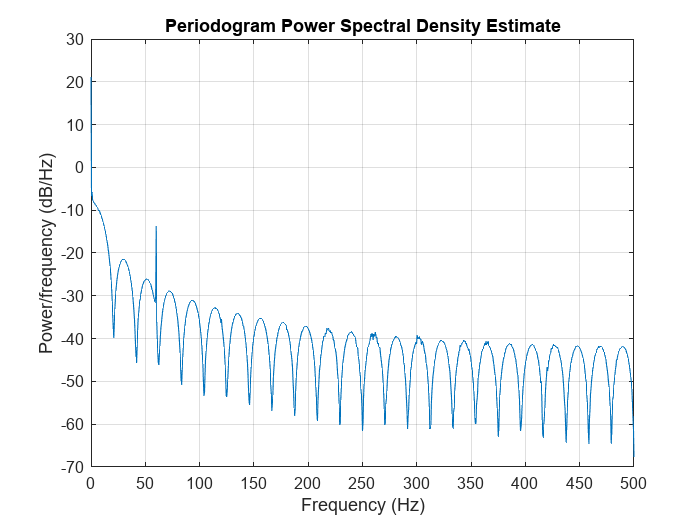

figure;
periodogram(openLoop, [], [], Fs);

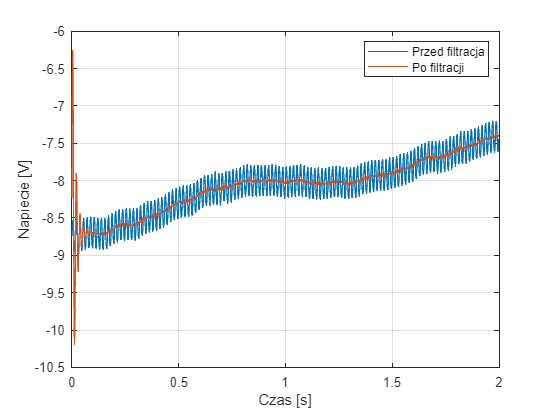

filtCoeff= designfilt('bandstopiir', 'FilterOrder', 2,...
'HalfPowerFrequency1', dolne, 'HalfPowerFrequency2', gorne, ...
'SampleRate', Fs);
fvtool(filtCoeff)
noiseFreeSignal= filter(filtCoeff, openLoop);
close all;
figure;
plot (t, openLoop, t, noiseFreeSignal); grid on;
legend('Przed filtracja', 'Po filtracji');
ylabel 'Napiecie [V]', xlabel 'Czas [s]'

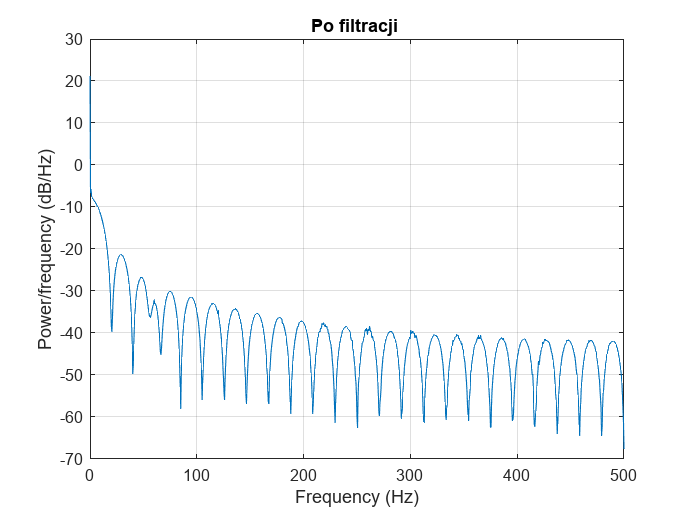

figure;
periodogram(noiseFreeSignal, [], [], Fs);
title('Po filtracji ');

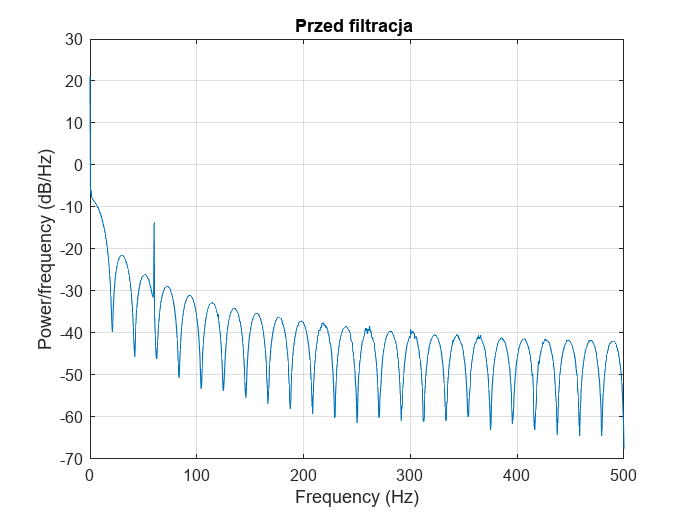

figure;
periodogram(openLoop, [], [], Fs);
title('Przed filtracja ');

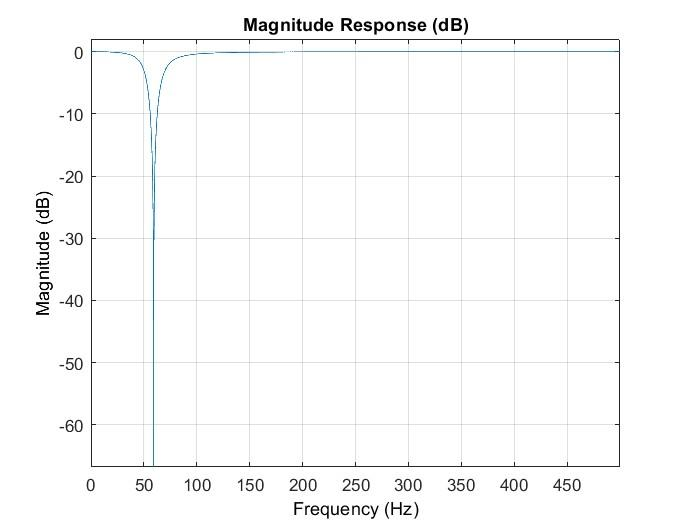

### Zadanie 2

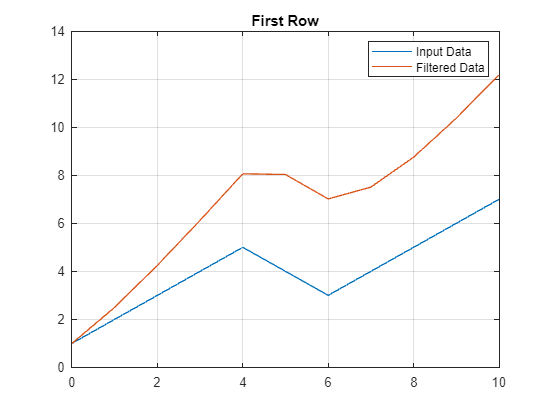

clear all;
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];
b = 1;
a = [1 -0.5];
y = filter(b,a,x,[],2);
t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:))
hold on
plot(t,y(1,:))
legend('Input Data','Filtered Data');grid on;
title('First Row')
hold off

### Zadanie 3

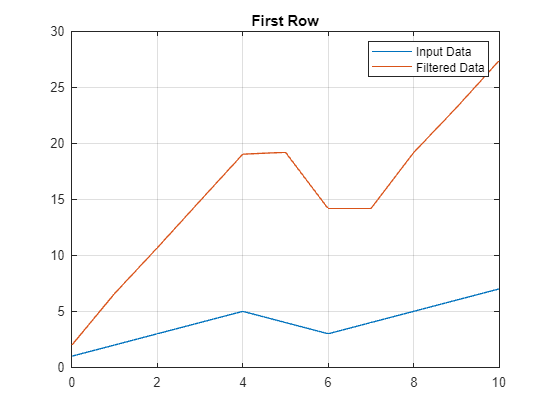

clear all;
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];
b = [2 3];
a = [1 0.2];
y = filter(b,a,x,[],2);
t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:))
hold on
plot(t,y(1,:))
legend('Input Data','Filtered Data');grid on;
title('First Row')
hold off

### Zadanie 4

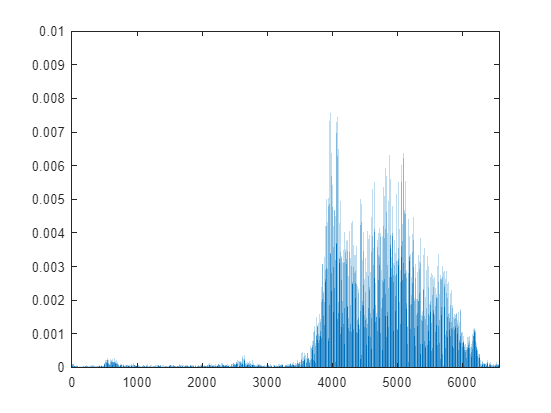

string = 'low';
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

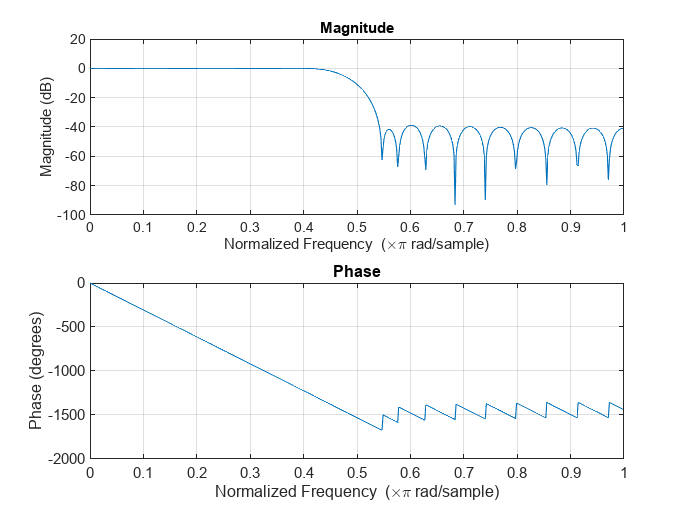

bhi = fir1(34,0.48,string ,chebwin(35,30));
freqz(bhi,1)

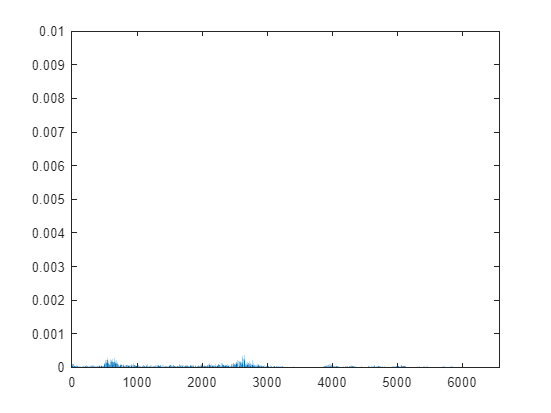

fvtool(bhi)
outhi = filter(bhi,1,y);
xfft=abs(fft(outhi));
xfft=xfft/13129;
x1=1:1:6564; 
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

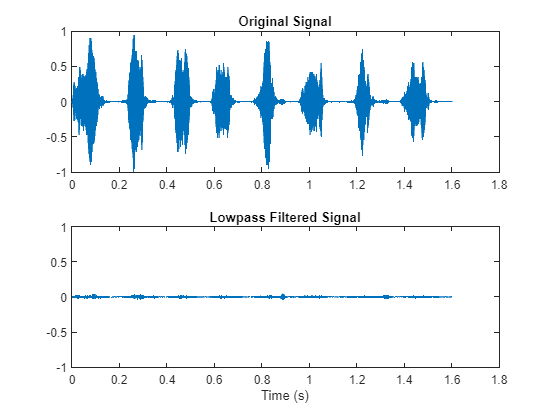

subplot(2,1,1)
plot(t,y)
title('Original Signal')
ys = ylim;
subplot(2,1,2)
plot(t,outhi)
title('Lowpass Filtered Signal')
xlabel('Time (s)')
ylim(ys)

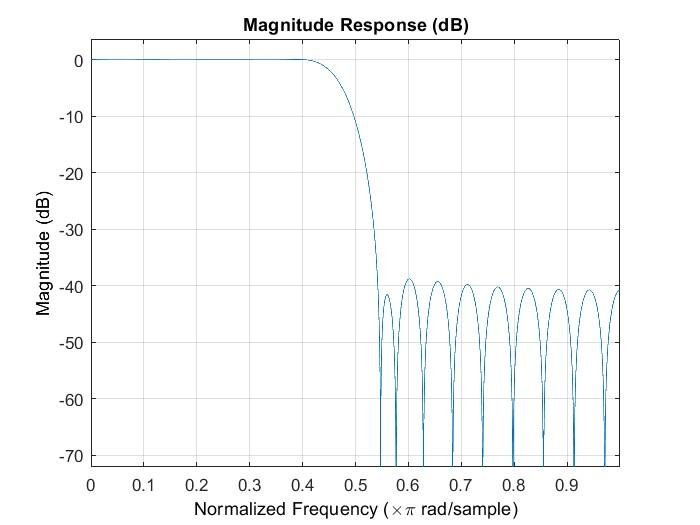

### Zadanie 5

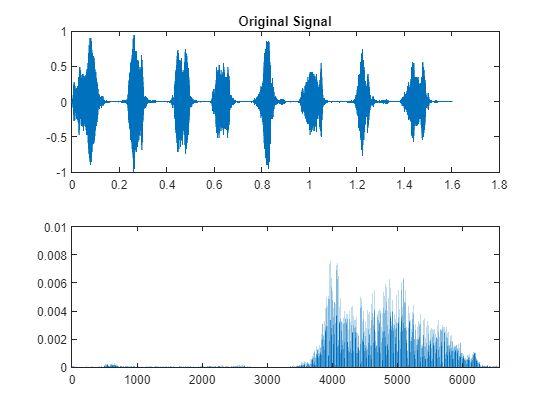

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
ord = 46;
low = 0.4;
bnd = [0.5 0.99];
bM = fir1(ord,[low bnd], 'DC-1');
bM1 = fir1(ord,[low bnd]);
fvtool(bM, 1, bM1, 1)
outF = filter(bM,1,y);
xfft=abs(fft(outF));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

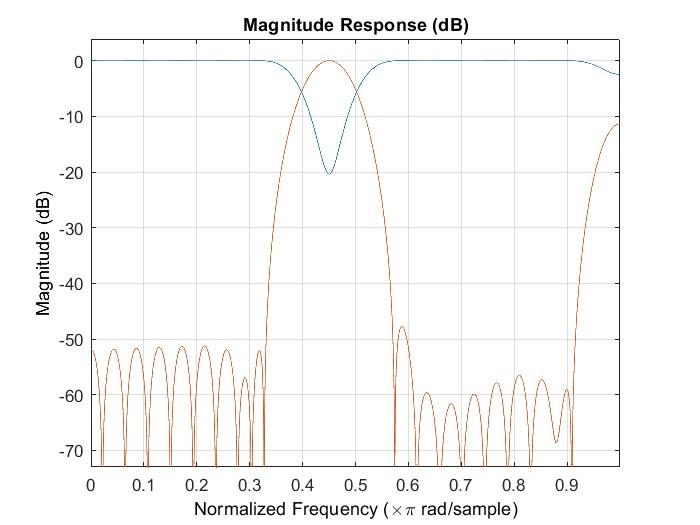

### Zadanie 6

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
ord = 46;
low = 0.4;
bnd = [0.5 0.99];
bM = fir1(ord,[low bnd], 'DC-1', tukeywin(ord+1));
hM = fir1(ord,[low bnd],'DC-0',hann(ord+1));
hfvt = fvtool(bM,1,hM,1); %porownanie okien
legend(hfvt,'Hamming','Hann')

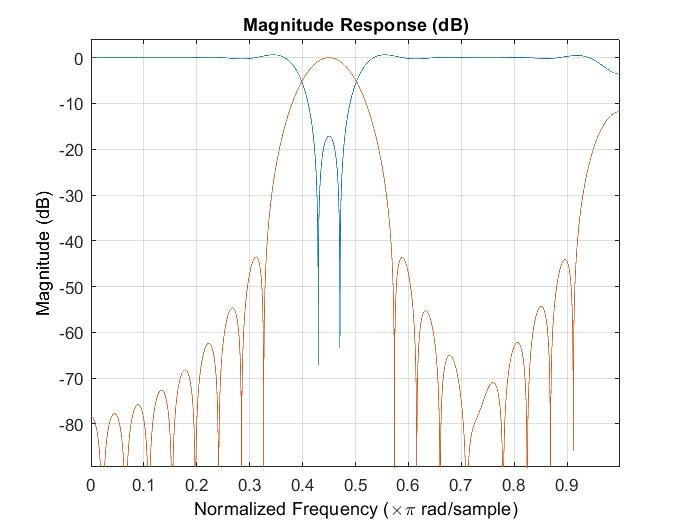

### Zadanie 7

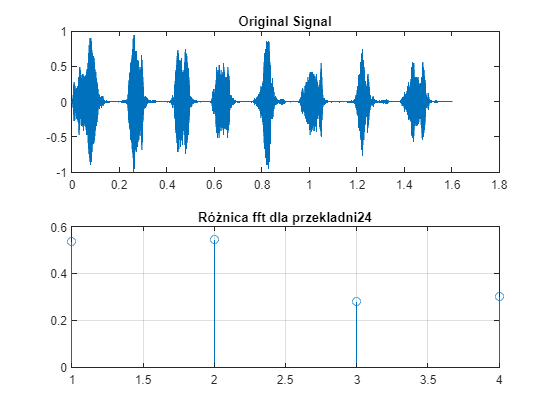

wiatrak20 = importdata("wiatrak_20.wav");
wiatrak21 = importdata("wiatrak_21.wav");
wiatrak23 = importdata("wiatrak_23.wav");
wiatrak24 = importdata("wiatrak_24.wav");
przekladnia20 = importdata("przekladnia20.wav");
przekladnia21 = importdata("przekladnia21.wav");
przekladnia23 = importdata("przekladnia23.wav");
przekladnia24 = importdata("przekladnia24.wav");

%dla wiatraka 20
data = wiatrak20.data;
max_data=max(abs(data));
data=data/max_data;
xfftw20=abs(fft(wiatrak20.data));
xfftw20=xfftw20/44100; 
xfftw20(1:501) = 0;
xfftw20(1001:44100) = 0;

% normalizacja do przedzialu [-1, 1] jesli sygnaly sa mierzone w roznych odleglosciach

%dla wiatraka 21


data = wiatrak21.data;
max_data1=max(abs(data));
data=wiatrak20.data/max_data1;
xfftw21=abs(fft(wiatrak21.data));
xfftw21=xfftw21/44100; 
xfftw21(1:501) = 0;
xfftw21(1001:44100) = 0;

%dla wiatraka 23
clear data; clear max_data1;

data = wiatrak23.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftw23=abs(fft(wiatrak23.data));
xfftw23=xfftw23/44100; 
xfftw23(1:501) = 0;
xfftw23(1001:44100) = 0;

%dla wiatraka 24
clear data; clear max_data1;

data = wiatrak24.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftw24=abs(fft(wiatrak24.data));
xfftw24=xfftw24/44100; 
xfftw24(1:501) = 0;
xfftw24(1001:44100) = 0;

%dla przekładni 20
clear data; clear max_data1;

data = przekladnia20.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp20=abs(fft(przekladnia20.data));
xfftp20=xfftp20/44100; 
xfftp20(1:501) = 0;
xfftp20(1001:44100) = 0;

%dla przekładni 21
clear data; clear max_data1;

data = przekladnia21.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp21=abs(fft(przekladnia21.data));
xfftp21=xfftp21/44100; 
xfftp21(1:501) = 0;
xfftp21(1001:44100) = 0;

%dla przekładni 23
clear data; clear max_data1;

data = przekladnia23.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp23=abs(fft(przekladnia23.data));
xfftp23=xfftp23/44100; 
xfftp23(1:501) = 0;
xfftp23(1001:44100) = 0;

%dla przekładni 24
clear data; clear max_data1;

data = przekladnia24.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp24=abs(fft(przekladnia24.data));
xfftp24=xfftp24/44100; 
xfftp24(1:501) = 0;
xfftp24(1001:44100) = 0;


D_w23= [];
D_w23(1)= sum(abs(xfftw23-xfftw20));
D_w23(2)= sum(abs(xfftw23-xfftw21));
D_w23(3)= sum(abs(xfftw23-xfftp20));
D_w23(4)= sum(abs(xfftw23-xfftp21));

D_w24= [];
D_w24(1)=sum(abs(xfftw24-xfftw20));
D_w24(2)=sum(abs(xfftw24-xfftw21));
D_w24(3)=sum(abs(xfftw24-xfftp20));
D_w24(4)=sum(abs(xfftw24-xfftp21));

D_p23= [];
D_p23(1)= sum(abs(xfftp23-xfftw20));
D_p23(2)= sum(abs(xfftp23-xfftw21));
D_p23(3)= sum(abs(xfftp23-xfftp20));
D_p23(4)= sum(abs(xfftp23-xfftp21));

D_p24= [];
D_p24(1)= sum(abs(xfftp24-xfftw20));
D_p24(2)= sum(abs(xfftp24-xfftw21));
D_p24(3)= sum(abs(xfftp24-xfftp20));
D_p24(4)= sum(abs(xfftp24-xfftp21));

stem(D_w23); grid on; title("Różnica fft dla wiatraka23");
stem(D_w24); grid on; title("Różnica fft dla wiatraka24");
stem(D_p23); grid on; title("Różnica fft dla przekladni23");
stem(D_p24); grid on; title("Różnica fft dla przekladni24");

### Zadanie 8

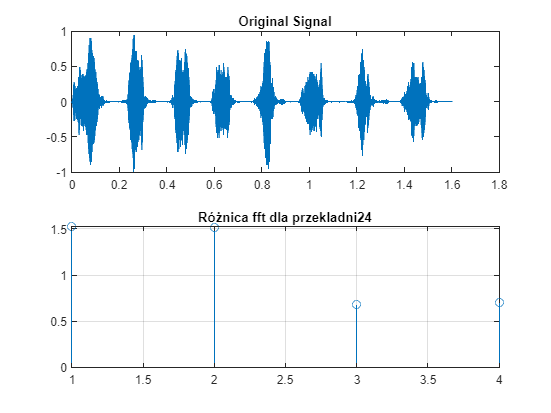

%dla wiatraka 20
data = wiatrak20.data;
max_data=max(abs(data));
data=data/max_data;
xfftw20=abs(fft(wiatrak20.data));
xfftw20=xfftw20/44100; 
xfftw20(1:101) = 0;
xfftw20(1501:44100) = 0;

% normalizacja do przedzialu [-1, 1] jesli sygnaly sa mierzone w roznych odleglosciach

%dla wiatraka 21


data = wiatrak21.data;
max_data1=max(abs(data));
data=wiatrak20.data/max_data1;
xfftw21=abs(fft(wiatrak21.data));
xfftw21=xfftw21/44100; 
xfftw21(1:101) = 0;
xfftw21(1501:44100) = 0;

%dla wiatraka 23
clear data; clear max_data1;

data = wiatrak23.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftw23=abs(fft(wiatrak23.data));
xfftw23=xfftw23/44100; 
xfftw23(1:101) = 0;
xfftw23(1501:44100) = 0;

%dla wiatraka 24
clear data; clear max_data1;

data = wiatrak24.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftw24=abs(fft(wiatrak24.data));
xfftw24=xfftw24/44100; 
xfftw24(1:101) = 0;
xfftw24(1501:44100) = 0;

%dla przekładni 20
clear data; clear max_data1;

data = przekladnia20.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp20=abs(fft(przekladnia20.data));
xfftp20=xfftp20/44100; 
xfftp20(1:101) = 0;
xfftp20(1501:44100) = 0;

%dla przekładni 21
clear data; clear max_data1;

data = przekladnia21.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp21=abs(fft(przekladnia21.data));
xfftp21=xfftp21/44100; 
xfftp21(1:101) = 0;
xfftp21(1501:44100) = 0;

%dla przekładni 23
clear data; clear max_data1;

data = przekladnia23.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp23=abs(fft(przekladnia23.data));
xfftp23=xfftp23/44100; 
xfftp23(1:101) = 0;
xfftp23(1501:44100) = 0;

%dla przekładni 24
clear data; clear max_data1;

data = przekladnia24.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp24=abs(fft(przekladnia24.data));
xfftp24=xfftp24/44100; 
xfftp24(1:101) = 0;
xfftp24(1501:44100) = 0;


D_w23= [];
D_w23(1)= sum(abs(xfftw23-xfftw20));
D_w23(2)= sum(abs(xfftw23-xfftw21));
D_w23(3)= sum(abs(xfftw23-xfftp20));
D_w23(4)= sum(abs(xfftw23-xfftp21));

D_w24= [];
D_w24(1)=sum(abs(xfftw24-xfftw20));
D_w24(2)=sum(abs(xfftw24-xfftw21));
D_w24(3)=sum(abs(xfftw24-xfftp20));
D_w24(4)=sum(abs(xfftw24-xfftp21));

D_p23= [];
D_p23(1)= sum(abs(xfftp23-xfftw20));
D_p23(2)= sum(abs(xfftp23-xfftw21));
D_p23(3)= sum(abs(xfftp23-xfftp20));
D_p23(4)= sum(abs(xfftp23-xfftp21));

D_p24= [];
D_p24(1)= sum(abs(xfftp24-xfftw20));
D_p24(2)= sum(abs(xfftp24-xfftw21));
D_p24(3)= sum(abs(xfftp24-xfftp20));
D_p24(4)= sum(abs(xfftp24-xfftp21));

stem(D_w23); grid on; title("Różnica fft dla wiatraka23");
stem(D_w24); grid on; title("Różnica fft dla wiatraka24");
stem(D_p23); grid on; title("Różnica fft dla przekladni23");
stem(D_p24); grid on; title("Różnica fft dla przekladni24");